**Writing Data to a File**

**Note: save only takes matrix and load only outputs a matrix. **

myMatrix = rand(2, 3)

myMatrix =     0.1524    0.5383    0.0782
    0.8258    0.9961    0.4427


save testMatrixFile.dat myMatrix -ascii

type testMatrixFile.dat


   1.5237802e-01   5.3834244e-01   7.8175529e-02
   8.2581698e-01   9.9613472e-01   4.4267827e-01


**Appending Data to File**

mat = randi([10,30],3,3)

mat =     12    26    11
    30    27    18
    10    28    15



save testMatrixFile.dat mat -ascii -append
type testMatrixFile.dat


   1.5237802e-01   5.3834244e-01   7.8175529e-02
   8.2581698e-01   9.9613472e-01   4.4267827e-01
   1.2000000e+01   2.6000000e+01   1.1000000e+01
   3.0000000e+01   2.7000000e+01   1.8000000e+01
   1.0000000e+01   2.8000000e+01   1.5000000e+01


**Reading from File**

clear
load testMatrixFile.dat
who


Your variables are:

testMatrixFile  



**Loading From File and Plotting**

xs = 0:3:21;
ys = [55.5 52.4 52.6 55.7 75.6 77.7 70.3 66.6];
mat = [xs; ys];
save TimeTemp.dat mat -ascii

% getting data
clear
load TimeTemp.dat 
xs = TimeTemp(1, :)

xs =      0     3     6     9    12    15    18    21


ys = TimeTemp(2, :)

ys =    55.5000   52.4000   52.6000   55.7000   75.6000   77.7000   70.3000   66.6000


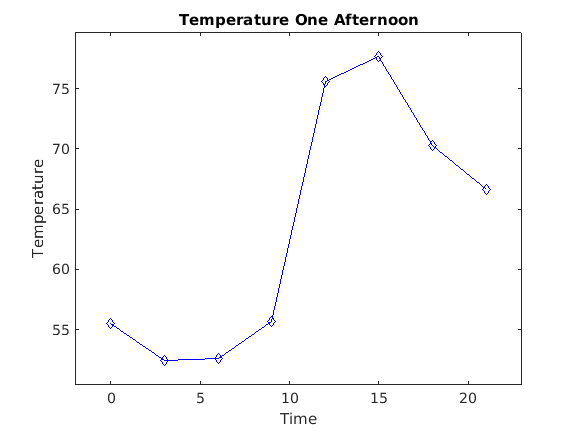

xMin = min(xs); xMax = max(xs);
yMin = min(ys); yMax = max(ys);

% Plotting
plot(xs, ys, 'bd-')
axis([xMin-2, xMax + 2, yMin-2, yMax+2])
xlabel('Time')
ylabel('Temperature')
title('Temperature One Afternoon')

% Flipping file into right format

xs = 1:4;
ys = [55.5 50.0 44.3 53.4];
mat = [xs; ys];
mat = fliplr(mat)'; % saving in bad format
save experiment.dat mat -ascii

clear
% load experiment.dat % or
mat = load('experiment.dat')

mat =     4.0000   53.4000
    3.0000   44.3000
    2.0000   50.0000
    1.0000   55.5000


who


Your variables are:

mat  




correctMat = flipud(mat)

correctMat =     1.0000   55.5000
    2.0000   50.0000
    3.0000   44.3000
    4.0000   53.4000


**Closed Cylinder Cost**

closedCylinderCost(32, 73, 4.50)

ans = 661.5000

fprintf('The cost would be $%.2f\n', ans)

The cost would be $661.50


type closedCylinderCost.m


function cost = closedCylinderCost(radius, height, costPerSquareFoot)
    % radius and height are in inches
    % cost is per square foot
    
    surfaceArea = 2*pi*radius .* height + 2*pi*radius .^ 2;
    
    % Convert surface area in square feet and round up
    surfaceAreaSqFeet = ceil(surfaceArea / 144);
    
    % Calculate cost in square feet
    cost = surfaceAreaSqFeet .* costPerSquareFoot;
end


type TimeTemp.dat


   0.0000000e+00   3.0000000e+00   6.0000000e+00   9.0000000e+00   1.2000000e+01   1.5000000e+01   1.8000000e+01   2.1000000e+01
   5.5500000e+01   5.2400000e+01   5.2600000e+01   5.5700000e+01   7.5600000e+01   7.7700000e+01   7.0300000e+01   6.6600000e+01
